# Capítulo 2 - Compensadores de Avanço e Atraso de fase.

*"Pra que diabos eu tenho que saber isso?", pergunta o estudante infeliz.*

Se algum dia, você for abordado na rua por algum maluco armado dizendo o seguinte:

*"Poderia me ajudar com este sistema instável? Não consigo projetar um compensador para poder deixar ele com as características que eu quero!!"*

Você pede para ele te dar um tiro na perna. Vai ser menos pior.

Resumo da ópera: Compensadores servem para alterar algumas características de um sistema (muitas vezes instável em uma faixa de valor K) sem alterar tanto o ganho do sistema. Compensadores servem principalmente para alterar a **FASE** do sistema. A alteração no ganho é um *efeito colateral *(muitas vezes indesejável). Muitas vezes, você recebe um sistema e precisa projetar um compensador para que ele, por exemplo, tenha um tempo de assentamento diferente, ou um overshoot menor, ou oscile menos. Isso depende muito dos requisitos que a questão (ou o seu chefe) pede.

Existem dois tipos de compensadores, o que desloca o LR pra esquerda (avanço de fase) e o que desloca o LR pra direita (atraso de fase). Todos os compensadores neste capítulo tem a inteção de adicionar um pólo e um zero (REAIS) no sistema para que o LR só sofra um deslocamento e atenda as necessidades do seu chefe.

*"Mas como fazer o LR deslocar sem alterar o formato dele? Já que estamos inserindo polos e zeros?", pergunta o estudante que não quer tomar um tiro na perna.*

Lembra de que o polo tende ao zero, conforme o ganho k aumenta? Vamos usar isso ao nosso favor. Vamos adicionar um par polo-zero (REAIS!) para que exista um caminho só pra eles e faça o centroide da assíntota dar uma deslocada para esquerda/direita.

## Tipos de compensadores

Vale ressaltar que não existe (fisicamente falando) um controlador que atua antes da entrada chegar, ou seja, o atraso ser negativo. Então, existe um limite no avanço da fase.

### Avanço de fase

Se você excitar (ui) esse sistema com uma senoidal, você vai ver que a fase dele vai dar uma avançada. Acho que é algo parecido com colocar um capacitor no sistema.

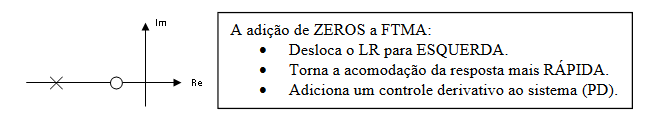

Mas pq desloca pra esquerda? -> Equação do centroide do material anterior vai te ajudar a lembrar

O tempo de acomodação costuma ser 4 vezes a constante de tempo. A constante de tempo é uma função do amortecimento e do wn. Ao jogar para a esquerda, você aumenta o valor de wn, diminuindo a constante de tempo e o tempo de acomodação (ver figura do passo a passo)

ehhhhhhhh, esse de adicionar um controle PD eu não lembro não. Só lembro que o zero se torna dominante, e adicionar zeros dominantes, é, na prática, um controle PD.

### Atraso de fase

Quando você precisa dar uma corrigida no erro estático do sistema. Vamos adicionar um polo dominante e um zero capenga ao sistema. É análogo (EU ACHO) a inserir um indutor ao circuito elétrico.

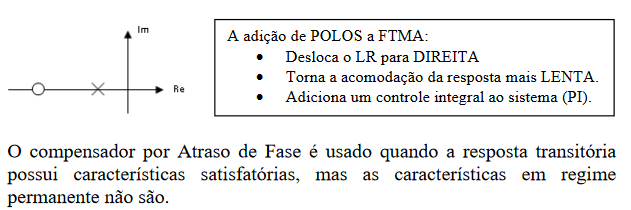

É trivial explicar as características desse daqui. É só pensar ao contrário do anterior.

## Atranço de fase (Atraso e Avanço)

Eu criei esse termo atranço. não usem na prova.

Você usa esse aqui para poder ferrar os alunos na prova.

Em relação ao sistema, você quer alterar a resposta em relação a certas frequências. Meio que adiciona filtros para que tenham algum atraso.

## Contribuição Angular

Todo compensador de avanço insere uma contribuição angular no sistema. Até porque, essa é a sua intenção, cacete.

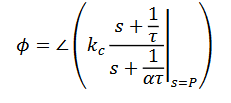A contribuição se dá nessa fórmula.

em que, 𝑃 é a posição do polo dominante da FTMF do sistema sem compensar. Essa contribuição define quanto da fase será avançada ou atrasada

## Passo a passo de como projetar um compensador

Como só vimos LR para sistemas RU e fase mínima, aqui vai ser parecido tbm (EU ACHO)

Primeiramente, a questão vai pedir que o seu controlador faça que o sistema tenha um novo comportamento. Esse comportamento pode ser traduzido como um ponto do LR. Você consegue traduzir as especificações do novo sistema utilizando essas equações:

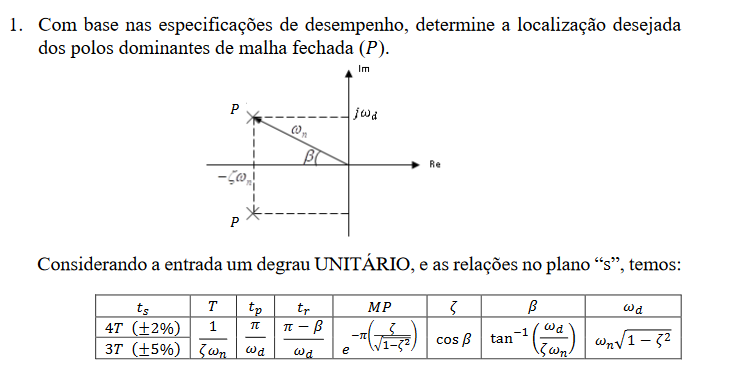

Desenhe o LR e veja se dá para chegar nesse ponto P apenas alterando o ganho (spoiler: não vai dar no geral)

Com o ponto P e o LR, você sabe se precisa jogar o LR para a esquerda ou direita, ou seja, se é um controlador de avanço ou atraso de fase.

Você precisa calcular a fase do ponto P e depois saber o quanto que o seu compensador precisa adicionar de fase para poder chegar lá.

Depois disso, vai vir uma trigonometria e geometria rasgando.

### Geometria rasgante

Você pode pular esse desenho todo quando possuir bastante prática. MAS, eu recomendaria atenção ao comparar o valor de $\varepsilon \;\mathrm{com}\frac{\phi }{2}$. Isso vai ficar mais claro no exemplo abaixo.

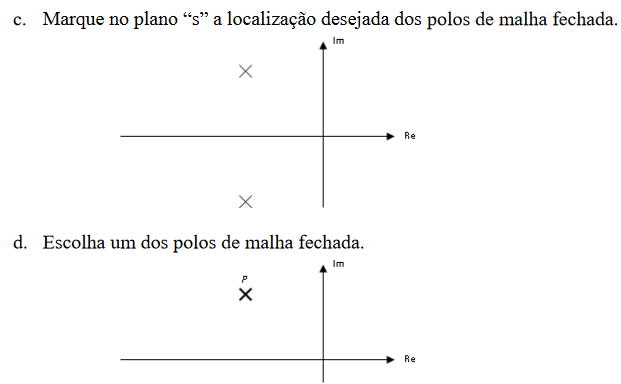

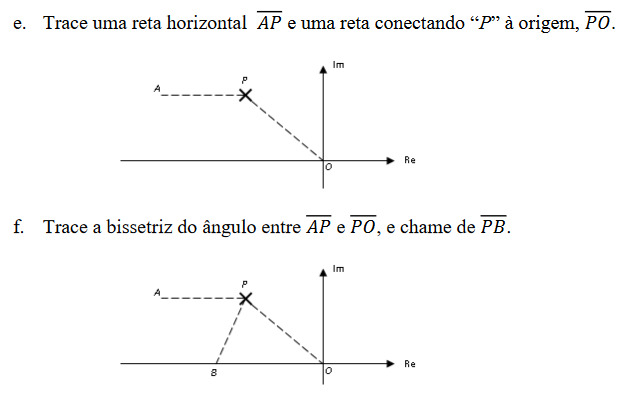

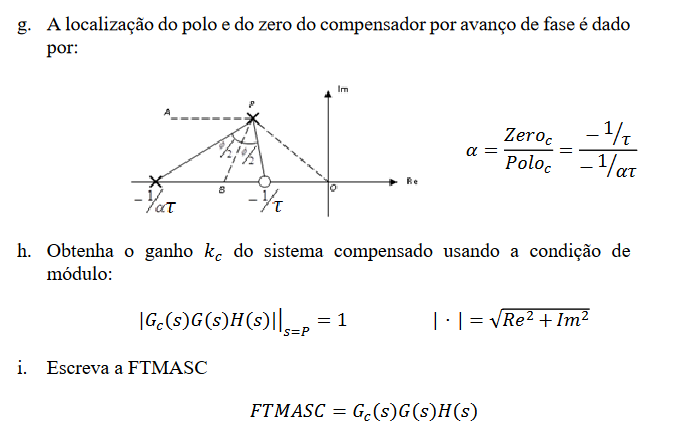

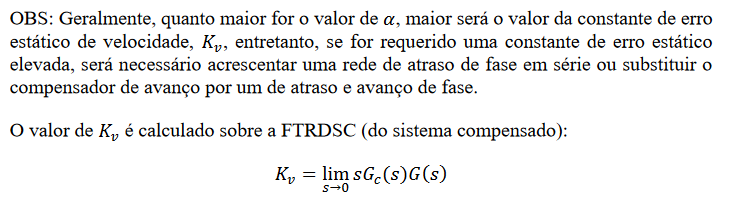

### Exemplo

Lembrando, **o foco aqui é saber quais são os polos e zeros do compensador e o ganho kc para chegar no ponto P**. Ver se realmente presta e rezar.

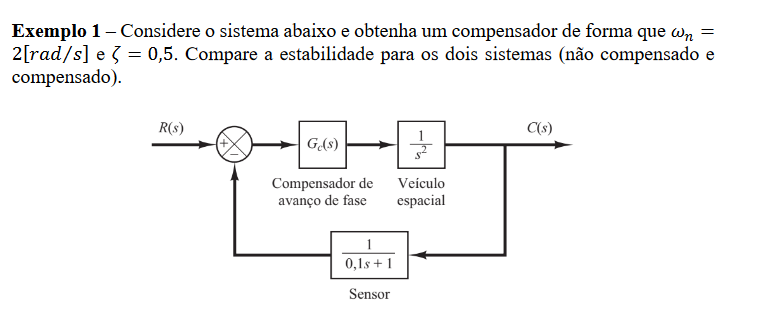

Vamos lá. Como dito, ele deu um sistema que está um LIXO e alguém (VOCÊ) precisa arrumar. O seu chefe pediu para que ele tenha as duas características principais wn e amortecimento. Essas características se traduzem como um ponto P no plano S. Então, vamos encontrar a fase e o módulo desse ponto (ou a parte Im e Real)

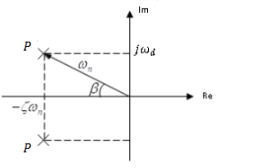Como o amortecimento é o cos (beta) = 0.5, então o ângulo é de +/-60º. (lembre-se que o ponto aparece conjugado)

o wn é o módulo da parte real com a imaginária, então temos um ponto P = 2/_60º = -1 +/- j*sqrt(3).

Vai ter que desenhar o lugar das raízes kkkkyring. Vou robar com o rootlocus

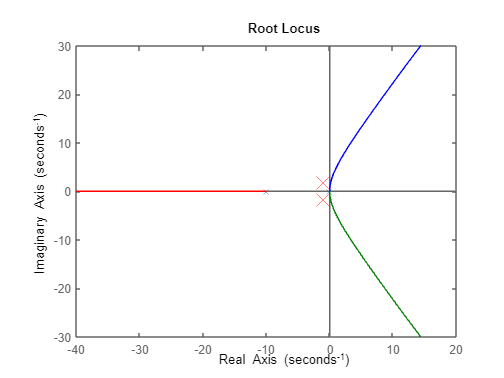

p1 = -1 + j*sqrt(3);
p2 = -1 - j*sqrt(3);
g = tf([1],[1,0,0]);
h = tf([1],[0.1,1]);
rlocusplot(g*h)
hold on
plot(real(p1),imag(p1),'rx','Markersize',15)
plot(real(p2),imag(p2),'rx','Markersize',15)
hold off

Vemos que, não adianta variar o k, esse diabo nunca vai passar lá nos pontos (dá pra usar as condições de fase e módulo também). É evidente que não ia dar pra ajustar o ganho, estamos aprendendo a fazer a parada namoral.

O próximo passo consiste em calcular a fase naquele ponto s=P e a contribuição angular necessária para o compensador.

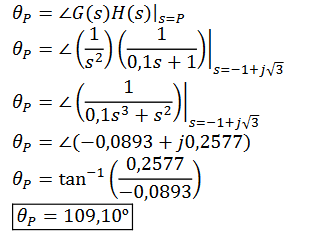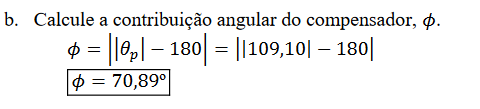

Essa parte aqui eu acredito que seja OK, não tem nada demais (posso errar na prova também, mas, positividade). **Baseado nessas fases e nos valores de P, vamos encontrar os polos e zeros dos compensadores que farão o LR se deslocar para lá.**

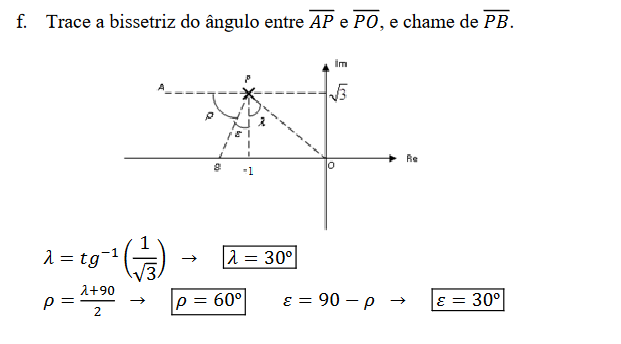

Agora vem a parte que é chata (como se a matéria toda não fosse)

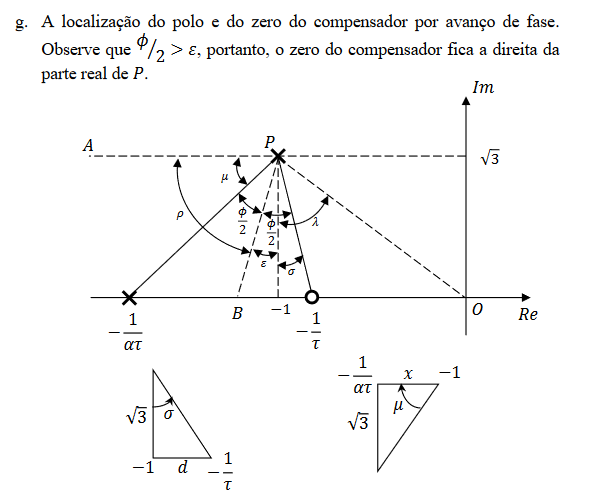

Agora é trigometria e geometria rasgando.

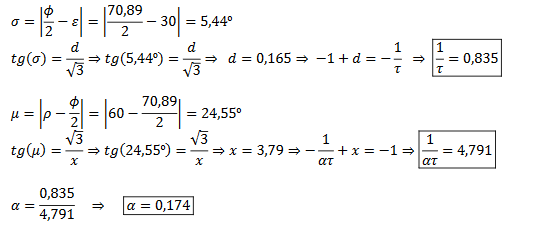

Esse alfa aí perdidão serve para ter uma noção do erro estático no futuro, não é muito importante nessa questão, já que ngm falou nada de erro estático.

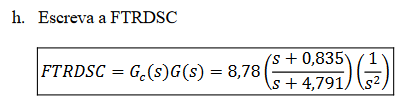(sei lá pra que vc quer isso, deve ser pra ver o ganho de 8,78)

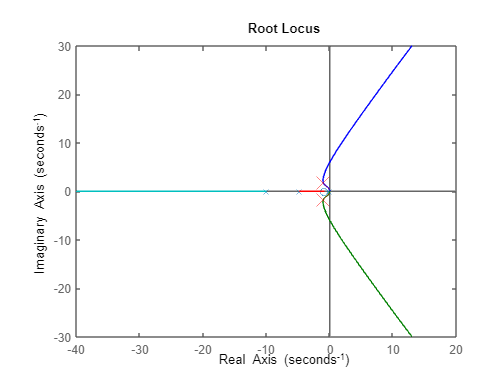

new_sys = 8.78 * zpk([-0.835],[-4.791],1) * g*h ;% novo LR
rlocus(new_sys)
hold on
plot(real(p1),imag(p1),'rx','Markersize',15)
plot(real(p2),imag(p2),'rx','Markersize',15)
hold off

Ainda bem que passou. Vale usar a condição de fase/módulo. 

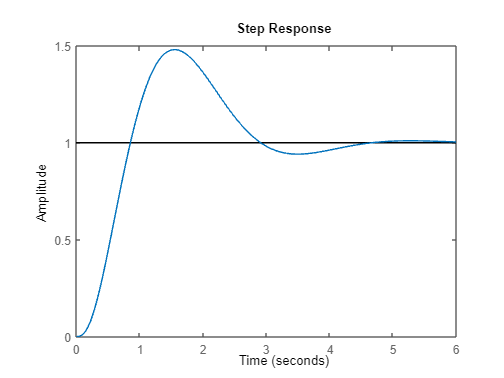

step(feedback(new_sys,1)) % o sistema antigo é instável para todos os valores de K.

### Outro exemplo

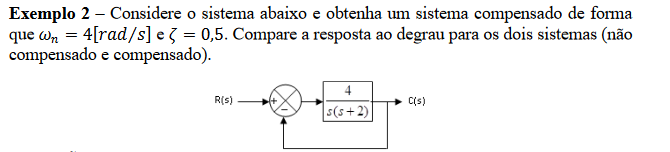

Vamos lá. Mesmo esquema anterior, achar o ponto P baseado em wn e no amortecimento.

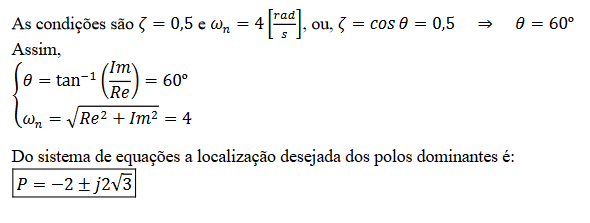

Vou roubar no rlocus aqui kkkkkkkkkkkkk

g = tf([4],[1,2,0]) % esse é a FTMA

g =
 
      4
  ---------
  s^2 + 2 s
 
Continuous-time transfer function.
Model Properties


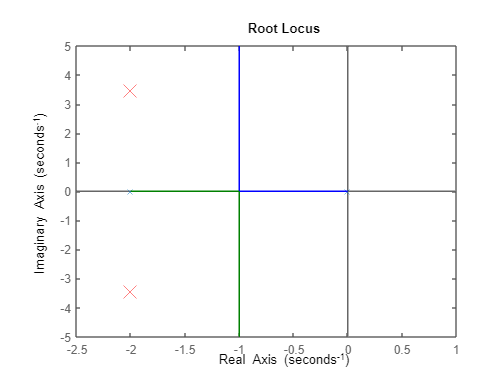

p1 = -2 + j*2*sqrt(3);
p2 = -2 - j*2*sqrt(3);
h2 = rlocusplot(g); % Use this command to return plot handle to programmatically customize the plot. 
p = getoptions(h2);
p.XLim = {[-2.5, 1]};
p.YLim = {[-5, 5]};
setoptions(h2,p);
hold on
plot(real(p1),imag(p1),'rx','Markersize',15)
plot(real(p2),imag(p2),'rx','Markersize',15)
hold off

Agora vamos ver a contribuição de fase necessária

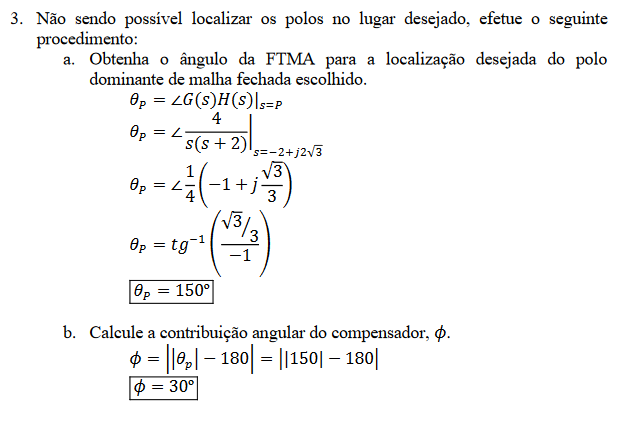

Agora a trigonometria maluca

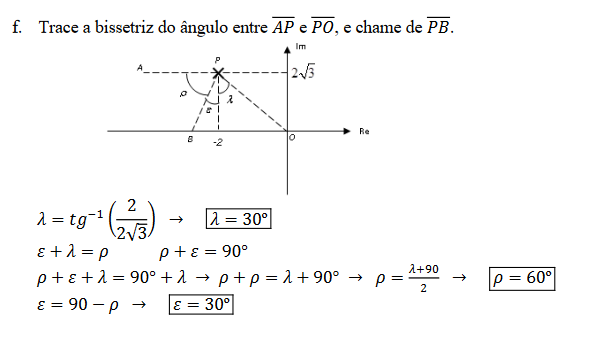

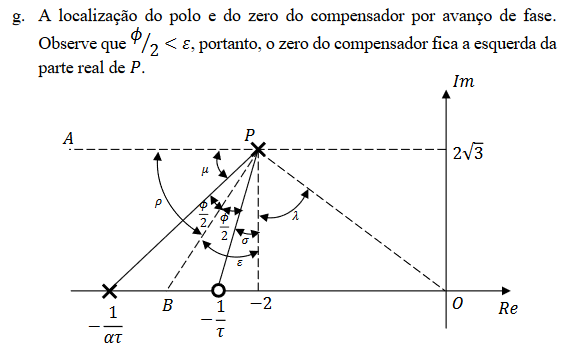

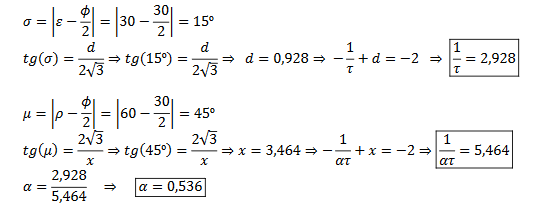

A partir disso, podemos calcular o ganho K para chegar naquele ponto

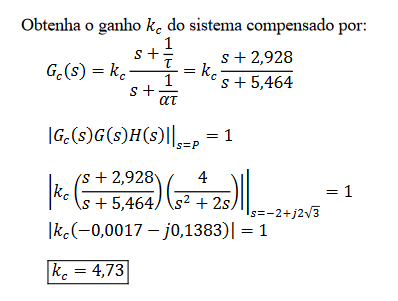

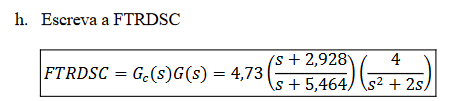

sys = 4.73*zpk([-2.928],[-5.464],1)*g

sys =
 
   18.92 (s+2.928)
  -----------------
  s (s+5.464) (s+2)
 
Continuous-time zero/pole/gain model.
Model Properties


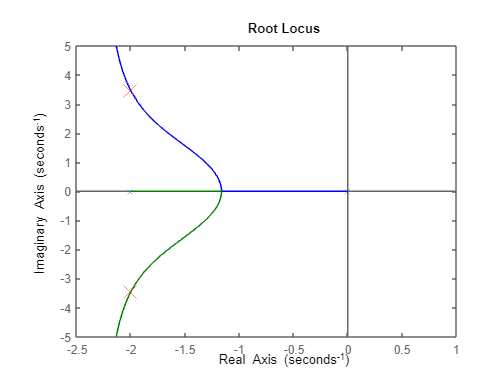

h2 = rlocusplot(sys); % Use this command to return plot handle to programmatically customize the plot. 
p = getoptions(h2);
p.XLim = {[-2.5, 1]};
p.YLim = {[-5, 5]};
setoptions(h2,p);
hold on
plot(real(p1),imag(p1),'rx','Markersize',15)
plot(real(p2),imag(p2),'rx','Markersize',15)
hold off

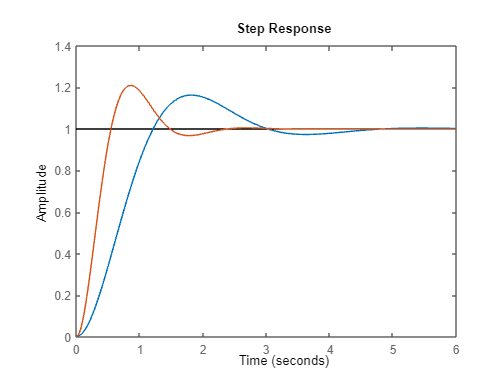

old_sys = feedback(tf([4],[1,2,0]),1);
sys = feedback(sys,1);
step(old_sys,sys)

### Pontos de atenção

Temos que ter os conceitos do capítulo 1 bem definidos para poder desenhar bem o LR. Se você não souber desenhar o LR, nem vai fazer a prova e reza para recuperar na final.

Dependendo de como você considera o valor do epslon e do phi/2, pode ser que você tenha que tomar um cuidado a mais na hora de colocar o zero.